# **Digital Equalizer**

## **Huzaifah Tariq Ahmed & Samiya Ali Zaidi**

### **For Filter Coefficients Conversion**

% Assuming 'filter' is a matrix containing your filter coefficients % Define the maximum positive value for 10-bit signed representation
max_positive_value = 511;
% Initialize a matrix to store the converted coefficients
filter_binary = zeros(size(Filter));
% Loop through each coefficient in the 'filter' matrix 
for i = 1:numel(Filter)
    % Scale the coefficient to fit within the 10-bit range
    scaled_coefficient = round(Filter(i) * max_positive_value);
    % Check if the coefficient is negative
    if scaled_coefficient < 0
        % Perform sign extension and convert to 10-bit binary representation
        filter_binary(i) = bin2dec([repmat('1',1,10-length(dec2bin(abs( scaled_coefficient)))) dec2bin(abs(scaled_coefficient))]);
    else
        % Convert positive coefficient to 10-bit binary representation
        filter_binary(i) = bin2dec(dec2bin(scaled_coefficient , 10));
    end 
end
% Display the original coefficients and their 10-bit signed binary representations
disp(['Original Coefficients: ' num2str(Filter)]);
disp(['Signed Binary Representation: ' num2str(filter_binary)]);

### **For Generating Tones**

**For 100Hz**:

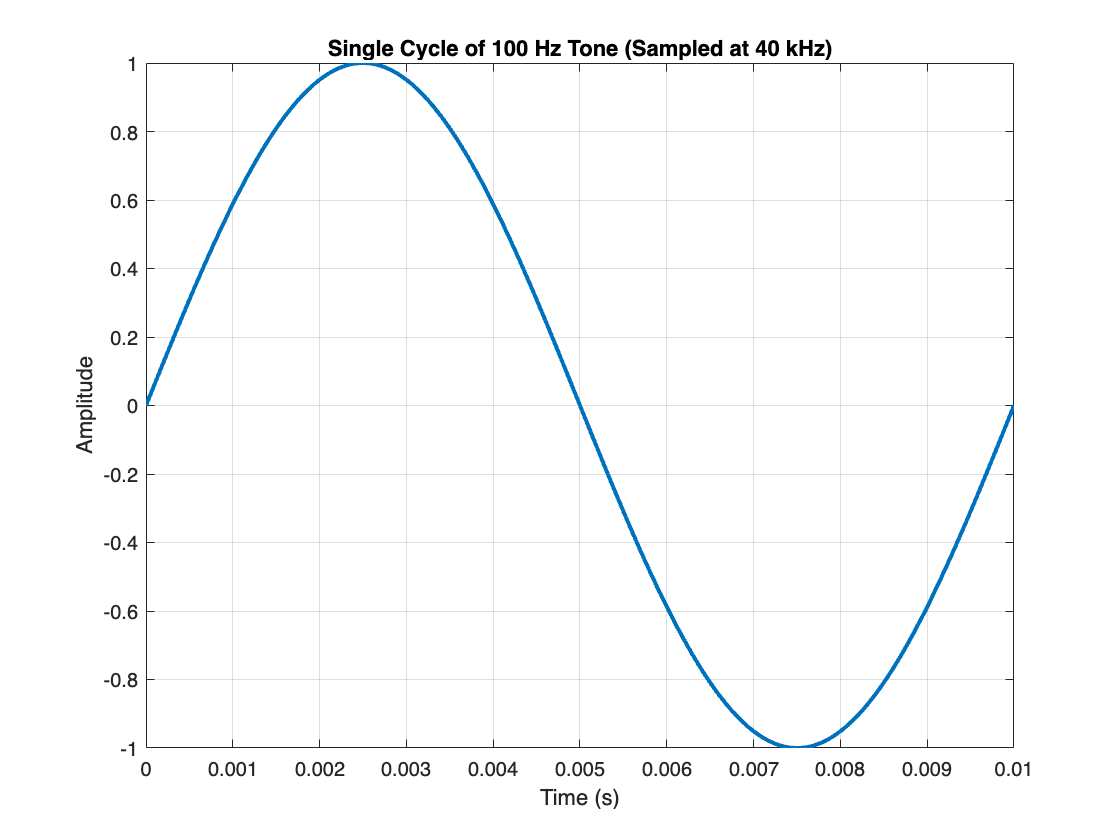

% Define the frequency and sampling rate
frequency = 100; % Frequency in Hz
sample_rate = 40000; % Sampling rate in Hz

% Calculate the period of the frequency
period = 1 / frequency; % Period in seconds

% Create a time vector for one cycle
% Generate a time vector from 0 to the period with step size 1/sample_rate
time_vector = 0:1/sample_rate:period;

% Generate the sine wave signal for a single cycle
% Note: To get a full cycle, the time vector should include the last point of the period
% So we use time_vector without removing the endpoint
tone = sin(2 * pi * frequency * time_vector);

% Plot the generated tone
figure;
plot(time_vector, tone, 'LineWidth', 2);
title('Single Cycle of 100 Hz Tone (Sampled at 40 kHz)');
xlabel('Time (s)');
ylabel('Amplitude'); grid on;


% Play the generated tone to hear the result
sound(tone, sample_rate)

% Save the sound signal as a WAV file
filename = '100Hz_Tone.wav'; % Name of the output WAV file
audiowrite(filename, tone, sample_rate); % Save the signal to a WAV file

**For 8KHz**:

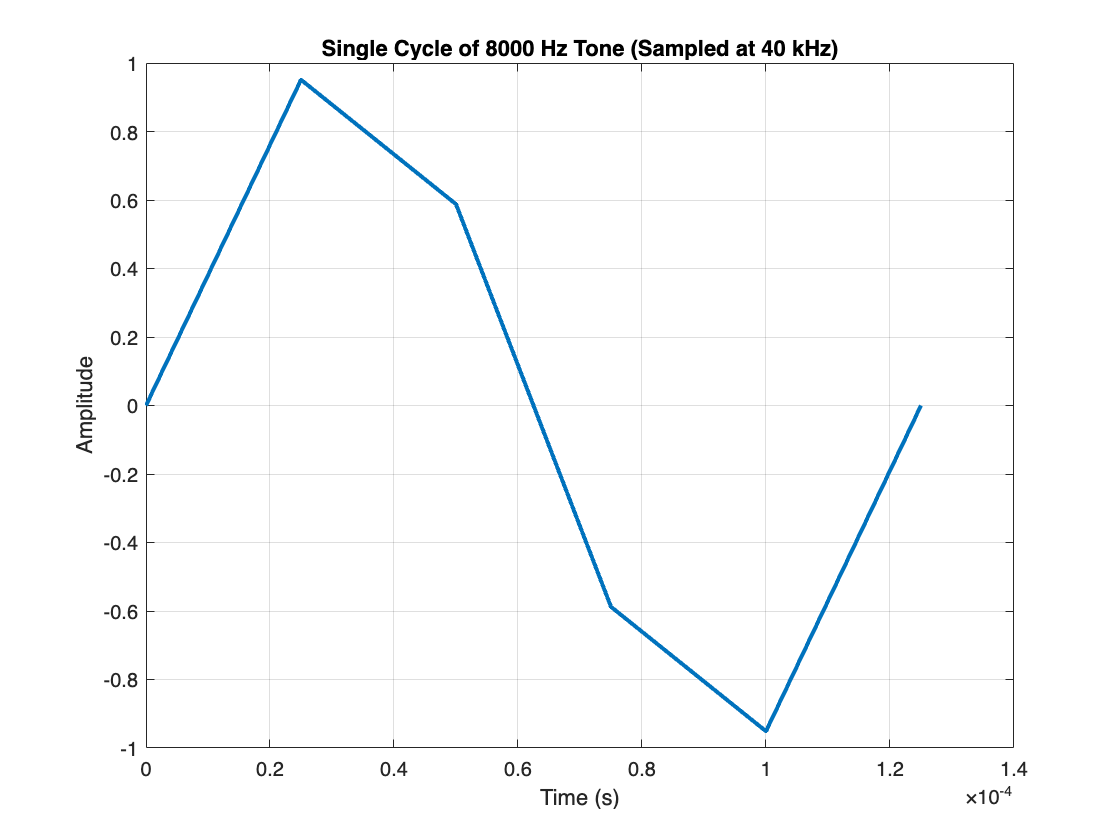

% Define the frequency and sampling rate
frequency = 8000; % Frequency in Hz

% Calculate the period of the frequency
period = 1 / frequency; % Period in seconds

% Create a time vector for one cycle
% Generate a time vector from 0 to the period with step size 1/sample_rate
time_vector_2 = 0:1/sample_rate:period;

% Generate the sine wave signal for a single cycle
% Note: To get a full cycle, the time vector should include the last point of the period
% So we use time_vector without removing the endpoint
tone2 = sin(2 * pi * frequency * time_vector_2);

% Plot the generated tone
figure;
plot(time_vector_2, tone2, 'LineWidth', 2);
title('Single Cycle of 8000 Hz Tone (Sampled at 40 kHz)');
xlabel('Time (s)');
ylabel('Amplitude'); grid on;

% Play the generated tone to hear the result
sound(tone2, sample_rate)

% Save the sound signal as a WAV file
filename = '8000Hz_Tone.wav'; % Name of the output WAV file
audiowrite(filename, tone2, sample_rate); % Save the signal to a WAV file

### **Filtering the Tones**

**Filtering the 100Hz wave:**

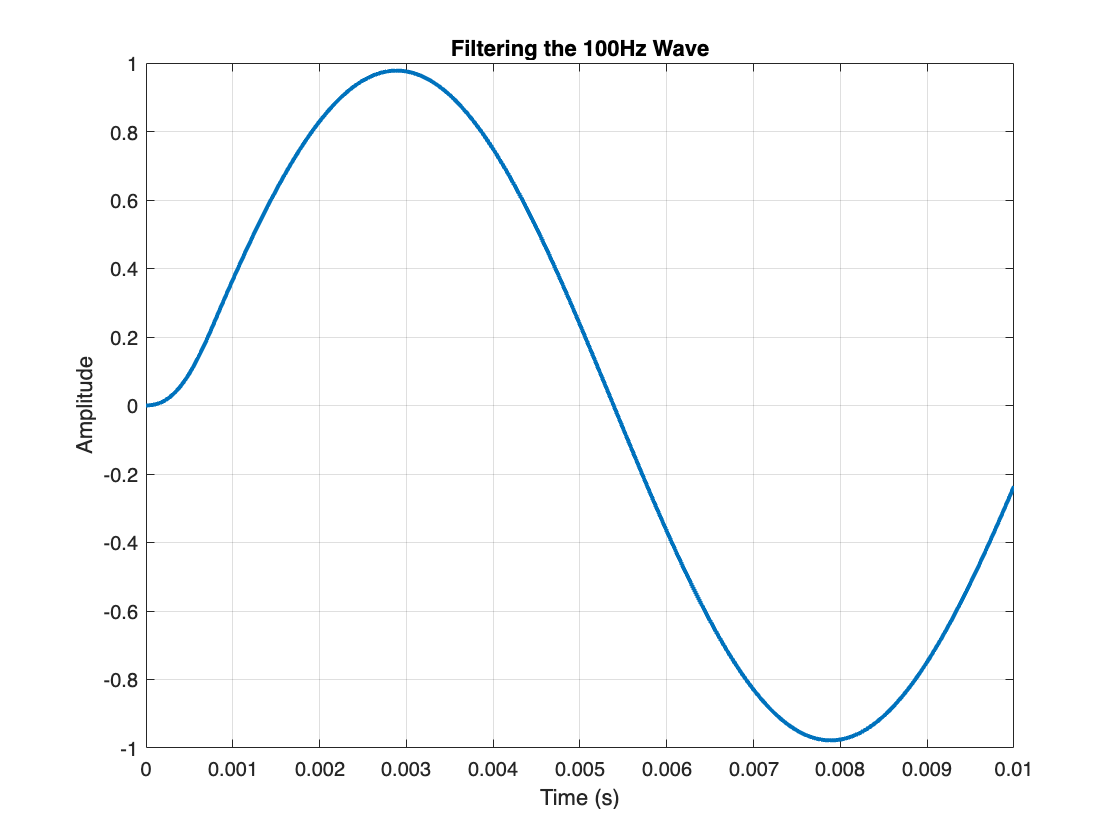

filtered = filter(Filter1, 1, tone);

plot(time_vector, filtered, 'LineWidth', 2);
ylabel("Amplitude"); xlabel("Time (s)"); grid on; 
title("Filtering the 100Hz Wave")

**Filtering the 8KHz wave**:

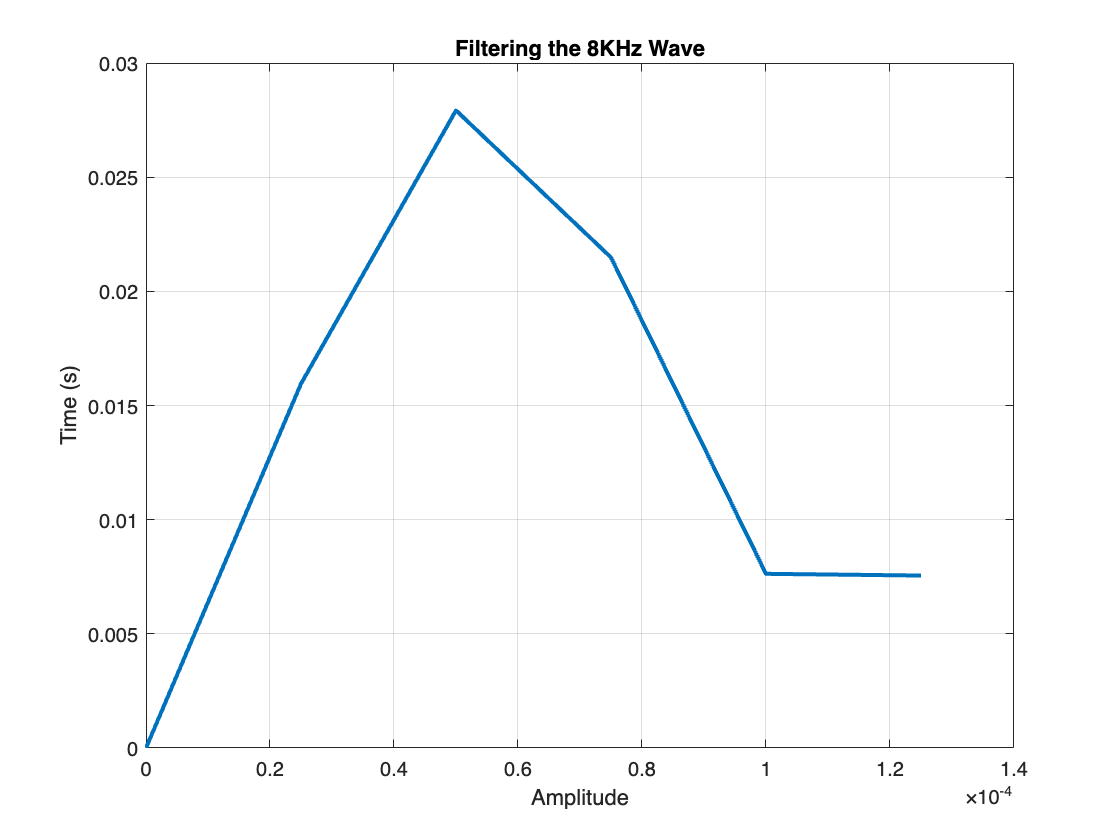

filtered = filter(Filter1, 1, tone2);

plot(time_vector_2, filtered, 'LineWidth', 2);
xlabel("Amplitude"); ylabel("Time (s)"); grid on; 
title("Filtering the 8KHz Wave")

#### **Writing the Audio File in .txt**

#### **Creating a Binary File for 100Hz**

% Step 1: Read the Audio File
audio_filename = '100Hz_Tone.wav'; % Name of the audio file to read
[audio_data, sample_rate] = audioread(audio_filename); % Read the audio file

% Step 2: Convert to 8-bit Signed Representation
% Scale the audio data to fit the -128 to 127 range
audio_data_scaled = audio_data * 127 % Scale to 8-bit signed integer range

audio_data_scaled =          0
    1.9921
    3.9881
    5.9803
    7.9724
    9.9606
   11.9489
   13.9333
   15.9138
   17.8943


audio_data_int8 = int8(audio_data_scaled); % Convert to 8-bit signed integers

% Step 3: Convert to 8-bit Binary Representation
% Convert each integer to its 8-bit binary string representation
binary_strings = arrayfun(@(x) dec2bin(typecast(x, 'uint8'), 8), audio_data_int8, 'UniformOutput', false);

% Step 4: Write to a Text File
txt_filename = 'audio_data_8bit_100Hz.txt'; % Name of the text file to create
file_id = fopen(txt_filename, 'w'); % Open in write mode

% Write each binary string on a new line
for i = 1:length(binary_strings)
    fprintf(file_id, '%s\n', binary_strings{i}); % Write the binary string
end

% Close the text file
fclose(file_id);

% Confirmation message
fprintf('Audio data saved as 8-bit signed binary representation in %s\n', txt_filename);

Audio data saved as 8-bit signed binary representation in audio_data_8bit_100Hz.txt


**For verification:**

% Step 1: Read the Text File with Binary Strings
txt_filename = 'audio_data_8bit_100Hz.txt'; % Name of the text file to read
file_id = fopen(txt_filename, 'r'); % Open the text file for reading
binary_strings = textscan(file_id, '%s'); % Read all lines as strings
fclose(file_id); % Close the file

% Flatten the cell array
binary_strings = binary_strings{1}; % Get the list of binary strings

% Step 2: Convert the Binary Strings to Unsigned Decimal
unsigned_values = cellfun(@(x) bin2dec(x), binary_strings); % Convert to decimal

% Step 3: Convert to Signed 8-bit Integers
% Convert to signed 8-bit integers
signed_values = unsigned_values; % Start with the unsigned values

% Apply two's complement logic for 8-bit signed integers
signed_values(signed_values > 127) = signed_values(signed_values > 127) - 256;

% Convert to int8 for clarity
signed_values = int8(signed_values);

% Step 4: Display the Converted Signed Decimal Values
disp('Binary strings and their corresponding signed decimal values:');

Binary strings and their corresponding signed decimal values:


for i = 1:length(binary_strings)
    fprintf('Binary: %s, Signed Decimal: %d\n', binary_strings{i}, signed_values(i));
end

Binary: 00000000, Signed Decimal: 0
Binary: 00000010, Signed Decimal: 2
Binary: 00000100, Signed Decimal: 4
Binary: 00000110, Signed Decimal: 6
Binary: 00001000, Signed Decimal: 8
Binary: 00001010, Signed Decimal: 10
Binary: 00001100, Signed Decimal: 12
Binary: 00001110, Signed Decimal: 14
Binary: 00010000, Signed Decimal: 16
Binary: 00010010, Signed Decimal: 18
Binary: 00010100, Signed Decimal: 20
Binary: 00010110, Signed Decimal: 22
Binary: 00011000, Signed Decimal: 24
Binary: 00011010, Signed Decimal: 26
Binary: 00011100, Signed Decimal: 28
Binary: 00011110, Signed Decimal: 30
Binary: 00100000, Signed Decimal: 32
Binary: 00100010, Signed Decimal: 34
Binary: 00100011, Signed Decimal: 35
Binary: 00100101, Signed Decimal: 37
Binary: 00100111, Signed Decimal: 39
Binary: 00101001, Signed Decimal: 41
Binary: 00101011, Signed Decimal: 43
Binary: 00101101, Signed Decimal: 45
Binary: 00101111, Signed Decimal: 47
Binary: 00110001, Signed Decimal: 49
Binary: 00110010, Signed Decimal: 50
Binary

#### **Creating a Binary File for 8000Hz**

% Step 1: Read the Audio File
audio_filename = '8000Hz_Tone.wav'; % Name of the audio file to read
[audio_data, sample_rate] = audioread(audio_filename); % Read the audio file

% Step 2: Convert to 8-bit Signed Representation
% Scale the audio data to fit the -128 to 127 range
audio_data_scaled = audio_data * 127 % Scale to 8-bit signed integer range

audio_data_scaled =          0
  120.7833
   74.6466
  -74.6505
 -120.7872
         0



audio_data_int8 = int8(audio_data_scaled); % Convert to 8-bit signed integers

% Step 3: Convert to 8-bit Binary Representation
% Convert each integer to its 8-bit binary string representation
binary_strings = arrayfun(@(x) dec2bin(typecast(x, 'uint8'), 8), audio_data_int8, 'UniformOutput', false);

% Step 4: Write to a Text File
txt_filename = 'audio_data_8bit_8000Hz.txt'; % Name of the text file to create
file_id = fopen(txt_filename, 'w'); % Open in write mode

% Write each binary string on a new line
for i = 1:length(binary_strings)
    fprintf(file_id, '%s\n', binary_strings{i}); % Write the binary string
end

% Close the text file
fclose(file_id);

% Confirmation message
fprintf('Audio data saved as 8-bit signed binary representation in %s\n', txt_filename);

Audio data saved as 8-bit signed binary representation in audio_data_8bit_8000Hz.txt


**For verification**

% Step 1: Read the Text File with Binary Strings
txt_filename = 'audio_data_8bit_8000Hz.txt'; % Name of the text file to read
file_id = fopen(txt_filename, 'r'); % Open the text file for reading
binary_strings = textscan(file_id, '%s'); % Read all lines as strings
fclose(file_id); % Close the file

% Flatten the cell array
binary_strings = binary_strings{1}; % Get the list of binary strings

% Step 2: Convert the Binary Strings to Unsigned Decimal
unsigned_values = cellfun(@(x) bin2dec(x), binary_strings); % Convert to decimal

% Step 3: Convert to Signed 8-bit Integers
% Convert to signed 8-bit integers
signed_values = unsigned_values; % Start with the unsigned values

% Apply two's complement logic for 8-bit signed integers
signed_values(signed_values > 127) = signed_values(signed_values > 127) - 256;

% Convert to int8 for clarity
signed_values = int8(signed_values);

% Step 4: Display the Converted Signed Decimal Values
disp('Binary strings and their corresponding signed decimal values:');

Binary strings and their corresponding signed decimal values:


for i = 1:length(binary_strings)
    fprintf('Binary: %s, Signed Decimal: %d\n', binary_strings{i}, signed_values(i));
end

Binary: 00000000, Signed Decimal: 0
Binary: 01111001, Signed Decimal: 121
Binary: 01001011, Signed Decimal: 75
Binary: 10110101, Signed Decimal: -75
Binary: 10000111, Signed Decimal: -121
Binary: 00000000, Signed Decimal: 0


### Plotting the filtered output

#### For 8Khz

% open the text file
file = fopen('log-8khz.txt', 'r');

% read the data
data = textscan(file, 'Time= %f, Filtered_Output: %s');

Error using textscan
Invalid file identifier. Use fopen to generate a valid file identifier.


% close the file
fclose(file);

% Step 4: Extract time and filtered output as binary strings
time = data{1};  % The first column is the time (as floating-point numbers)
binary_filtered_output = data{2};  % The second column is the filtered output (as binary strings)

% Step 5: Convert binary to signed decimal integers
filtered_output = zeros(size(binary_filtered_output));  % Preallocate array

for i = 1:length(binary_filtered_output)
    binary_str = binary_filtered_output{i};  % Get the binary string
    sign_bit = binary_str(1);  % Most significant bit (sign bit)
    
    if sign_bit == '1'  % Negative number (two's complement)
        % Flip bits, convert to decimal, and add 1
        flipped_bits = binary_str;
        flipped_bits(flipped_bits == '0') = '1';
        flipped_bits(flipped_bits == '1') = '0';
        decimal_value = bin2dec(flipped_bits) + 1;  % Convert to decimal
        filtered_output(i) = -decimal_value;  % Convert to negative
    else  % Positive number
        filtered_output(i) = bin2dec(binary_str);  % Convert to decimal
    end
end

% display the arrays
disp('Time:');
disp(time);
disp('Data:');
disp(filtered_output);

% Given `filtered_output` as an array of signed decimal numbers

% Step 1: Extract the initial 15 values from `filtered_output`
initial_15_values = filtered_output(1:15);  % Take the first 15 elements

% Step 2: Divide by 511
scaled_values = initial_15_values / 511;  % Divide by 511

% Step 3: Display the results
disp('Initial 15 Values Scaled by 1/511:');
disp(scaled_values);

scaled_values_new = scaled_values / 127;
disp('All Scaling Done:');
disp(scaled_values_new);
figure;
plot(time(1:15), scaled_values_new, 'LineWidth', 2);
xlabel("time");
ylabel("Amplitude");
title("Filtered 8KHz signal from verilog");
grid on;
ylim([-1 1])

% open the text file
file = fopen('log-100Hz.txt', 'r');

% read the data
data = textscan(file, 'Time= %f, Filtered_Output: %s');

% close the file
fclose(file);

% Step 4: Extract time and filtered output as binary strings
time = data{1};  % The first column is the time (as floating-point numbers)
binary_filtered_output = data{2};  % The second column is the filtered output (as binary strings)

% Step 5: Convert binary to signed decimal integers
filtered_output = zeros(size(binary_filtered_output));  % Preallocate array

for i = 1:length(binary_filtered_output)
    binary_str = binary_filtered_output{i};  % Get the binary string
    sign_bit = binary_str(1);  % Most significant bit (sign bit)
    
    if sign_bit == '1'  % Negative number (two's complement)
        % Flip bits, convert to decimal, and add 1
        flipped_bits = binary_str;
        flipped_bits(flipped_bits == '0') = '1';
        flipped_bits(flipped_bits == '1') = '0';
        decimal_value = bin2dec(flipped_bits) + 1;  % Convert to decimal
        filtered_output(i) = -decimal_value;  % Convert to negative
    else  % Positive number
        filtered_output(i) = bin2dec(binary_str);  % Convert to decimal
    end
end

% display the arrays
disp('Time:');
disp(time);
disp('Data:');
disp(filtered_output);

% Given `filtered_output` as an array of signed decimal numbers

% Step 1: Extract the initial 15 values from `filtered_output`
% initial_15_values = filtered_output(1:15);  % Take the first 15 elements

% Step 2: Divide by 511
scaled_values = filtered_output / 511;  % Divide by 511

% Step 3: Display the results
disp('Initial 15 Values Scaled by 1/511:');
disp(scaled_values);

scaled_values_new = scaled_values / 127;
disp('All Scaling Done:');
disp(scaled_values_new);

figure;
plot(time, scaled_values_new, 'LineWidth', 2);
xlabel("time");
ylabel("Amplitude");
title("Filtered 100Hz signal from verilog");
grid on;
ylim([-1 1])

check

% open the text file
file = fopen('check.txt', 'r');

% read the data
% data = textscan(file, 'Time= %f, Filtered_Output: %s, ROM_Data: %s', 'Delimiter', ',');
%data = fscanf(file, 'Time= %f, Filtered_Output: %s, ROM_Data: %s\n', [3, Inf]);
data = textscan(file, 'Time= %d, Filtered_Output: %s, ROM_Data: %s', 'Delimiter', ',', 'Whitespace', ' \t');

Error using textscan
Invalid file identifier. Use fopen to generate a valid file identifier.

% close the file
fclose(file);

% Step 4: Extract time and filtered output as binary strings
time = data{1};  % The first column is the time (as floating-point numbers)
binary_filtered_output = data{2};  % The second column is the filtered output (as binary strings)
binary_original = data{3};

disp(time);
disp(binary_filtered_output);
disp(binary_original);
% Step 5: Convert binary to signed decimal integers
filtered_output = zeros(size(binary_original));  % Preallocate array

for i = 1:length(binary_original)
    binary_str = binary_original{i};  % Get the binary string
    sign_bit = binary_str(1);  % Most significant bit (sign bit)
    
    if sign_bit == '1'  % Negative number (two's complement)
        % Flip bits, convert to decimal, and add 1
        flipped_bits = binary_str;
        flipped_bits(flipped_bits == '0') = '1';
        flipped_bits(flipped_bits == '1') = '0';
        decimal_value = bin2dec(flipped_bits) + 1;  % Convert to decimal
        filtered_output(i) = -decimal_value;  % Convert to negative
    else  % Positive number
        filtered_output(i) = bin2dec(binary_str);  % Convert to decimal
    end
end

% display the arrays
disp('Time:');
disp(time);

disp('Data:');
disp(filtered_output);

% Given `filtered_output` as an array of signed decimal numbers

% Step 1: Extract the initial 15 values from `filtered_output`
% initial_15_values = filtered_output(1:15);  % Take the first 15 elements

% Step 2: Divide by 511
scaled_values = filtered_output / 511;  % Divide by 511

% Step 3: Display the results
disp('Initial 15 Values Scaled by 1/511:');
disp(scaled_values);

scaled_values_new = scaled_values / 127;
disp('All Scaling Done:');
disp(scaled_values_new);

figure;
plot(time, scaled_values_new, 'LineWidth', 2);
xlabel("time");
ylabel("Amplitude");
title("Filtered 100Hz signal from verilog");
grid on;
ylim([-1 1])